# Solution 12.3 - Solution for Example 12.3 from Week 7 notes.

syms s t v_out V_out

Setup the problem

eq45 = (V_out - 1 - 3/s)/(1/s + 2 + s/2) + V_out/1 + V_out/(s/2) == 0

$$eq45 = V_{\mathrm{out}}-\frac{\frac{3}{s}-V_{\mathrm{out}}+1}{\frac{s}{2}+\frac{1}{s}+2}+\frac{2\,V_{\mathrm{out}}}{s}=0$$

V_out = solve(eq45, V_out)

$$V\_out = \frac{2\,s^{2}+6\,s}{s^{3}+8\,s^{2}+10\,s+4}$$

 In the lecture we showed that after simplification for Example 12.3

$V_{\mathrm{o}\mathrm{u}\mathrm{t}} (s)=\frac{2s(s+3)}{s^3 +8s^2 +10s+4}\;$(1)

V_out

$$V\_out = \frac{2\,s^{2}+6\,s}{s^{3}+8\,s^{2}+10\,s+4}$$

We will use MATLAB to factorize the denominator $D(s)$ of the equation into a linear and a quadratic factor.

Note that, when the denominator is factorized, equation (1) will be

$V_{\mathrm{o}\mathrm{u}\mathrm{t}} (s)=\frac{2s(s+3)}{(s-p_1 )(s-p_2 )(s-p_3 )}$ (2)

where $p_1 \;$is real and $p_2$ and $p_3 \;$are complex with $p_3 =p_2^*$ (the complex conjugate of $p_2$).

Declare the denominator of `Vout` to be a polynomial in s

syms s t
Ds = s^3 + 8*s^2 + 10*s + 4

$$Ds = s^{3}+8\,s^{2}+10\,s+4$$

Convert `Ds` to a MATLAB polynomial using `sym2poly`

d = sym2poly(Ds)

d =      1     8    10     4


Find roots of $D\left(s\right)$

format long
p = roots(d)

p =  -6.570750563722639 + 0.000000000000000i
 -0.714624718138679 + 0.313161257350729i
 -0.714624718138679 - 0.313161257350729i


Store real pole as `p1`

p1 = p(1)

p1 =   -6.570750563722639

Find quadratic form

qs = expand((s - p(2))*(s - p(3)))

$$qs = s^{2}+\frac{804595903579775\,s}{562949953421312}+\frac{3086772113315577969665007046981}{5070602400912917605986812821504}$$

Simplify coefficients of `qs` and return a numerical polynomial vector

q = sym2poly(qs)

q =    1.000000000000000   1.429249436277358   0.608758460880276


## Now use inverse Laplace transform to solve

Define the factors of the denominator and rewrite `Vout` in factored form.

You will need `p1` and `q` from the previous section

Ns = 2*s*(s+3)

$$Ns = 2\,s\,\left(s+3\right)$$

Ds = (s - p(1))*qs

$$Ds = \left(s+\frac{3699003723790719}{562949953421312}\right)\,\left(s^{2}+\frac{804595903579775\,s}{562949953421312}+\frac{3086772113315577969665007046981}{5070602400912917605986812821504}\right)$$


V_out(s) = Ns/Ds

$$V\_out(s) = \frac{2\,s\,\left(s+3\right)}{\left(s+\frac{3699003723790719}{562949953421312}\right)\,\left(s^{2}+\frac{804595903579775\,s}{562949953421312}+\frac{3086772113315577969665007046981}{5070602400912917605986812821504}\right)}$$

Exact solution

v_out(t) = ilaplace(V_out(s))

$$v\_out(t) = \frac{237938132050491874560868586463264\,{\mathrm{e}}^{-\frac{3699003723790719\,t}{562949953421312}}}{174389576995383734106207237906757}+\frac{110841021940275593651545889350250\,{\mathrm{e}}^{-\frac{804595903579775\,t}{1125899906842624}}\,\left(\cos\left(\frac{705176460955809\,t}{2251799813685248}\right)-\frac{114001779759373874310224037861047984203122362242\,\sin\left(\frac{705176460955809\,t}{2251799813685248}\right)}{39081239790284360447654239336025710034486551125}\right)}{174389576995383734106207237906757}$$

Approximate solution 

var = vpa(v_out,3)

$$var(t) = 1.36\,{\mathrm{e}}^{-6.57\,t}+0.636\,{\mathrm{e}}^{-0.715\,t}\,\left(\cos\left(0.313\,t\right)-2.92\,\sin\left(0.313\,t\right)\right)$$

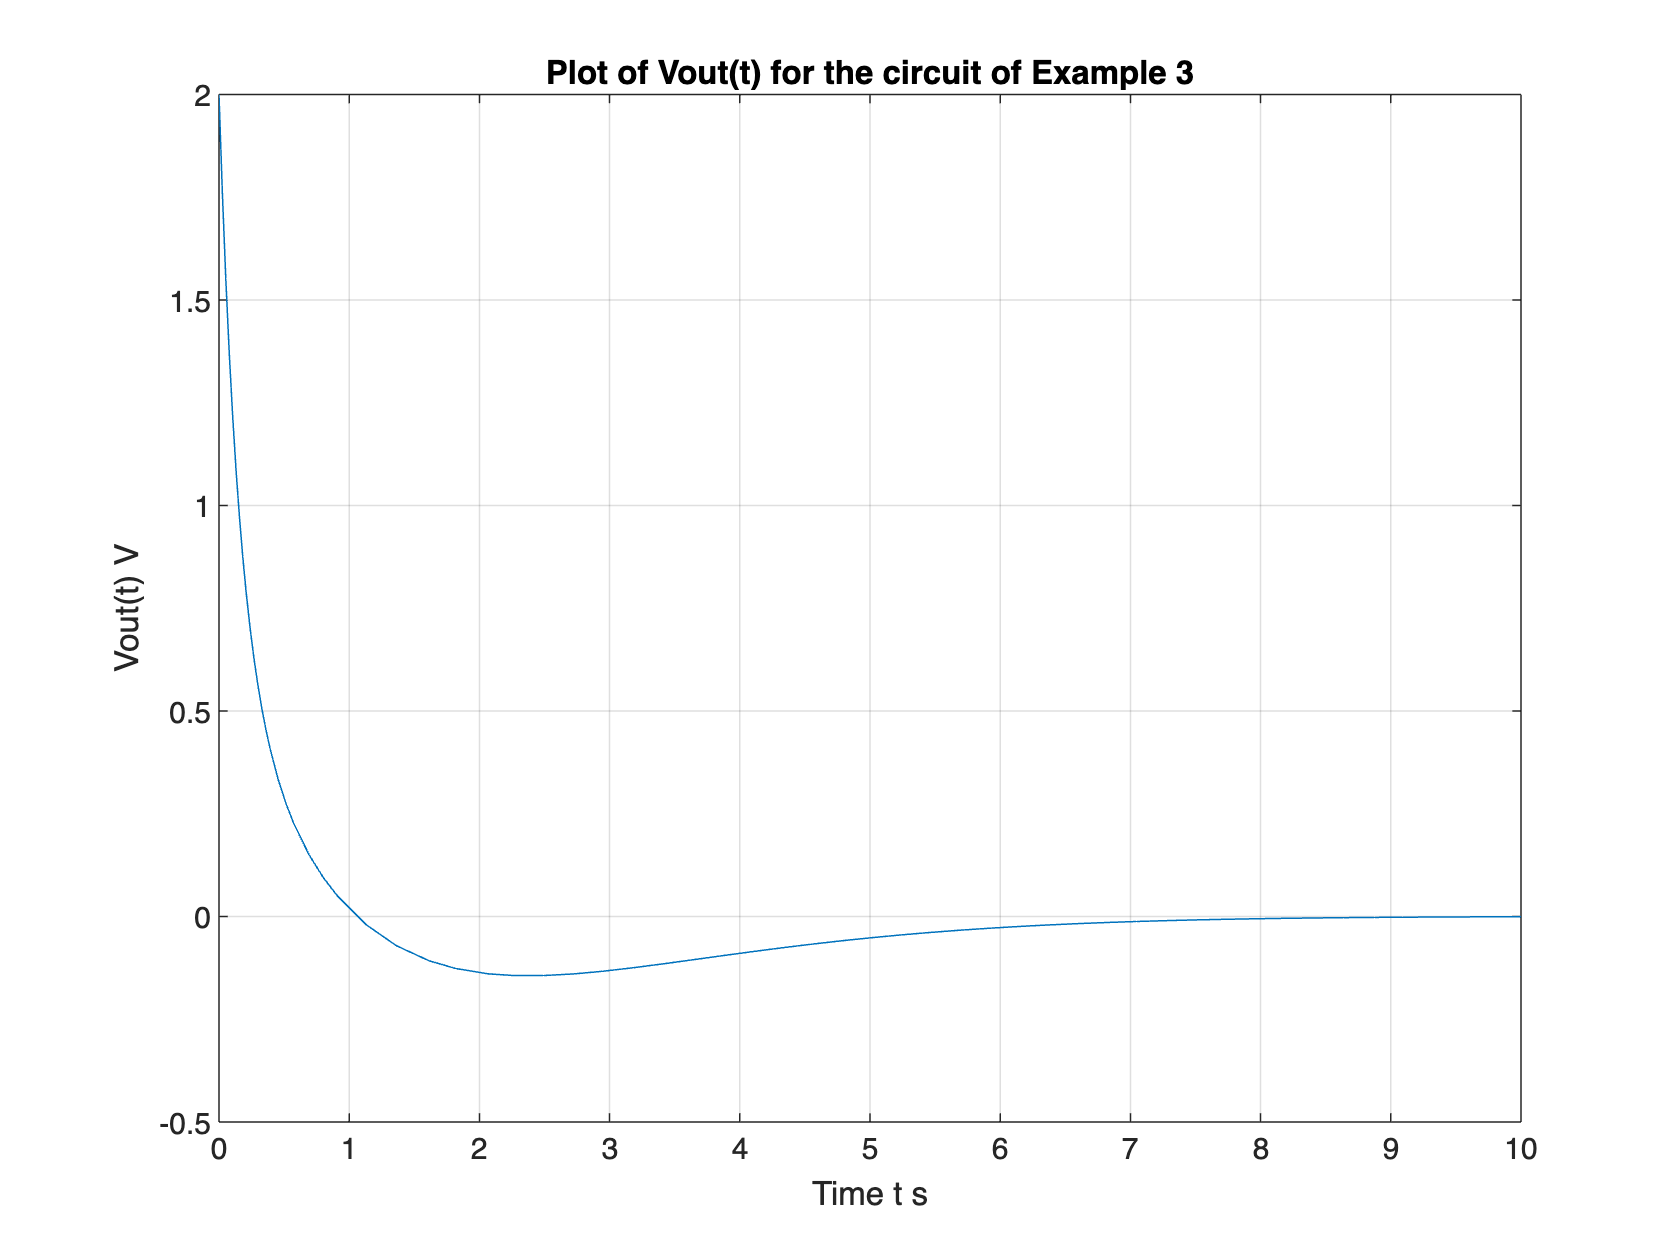

% % Plot result
fplot(v_out(t),[0,10]),...
    ylim([-0.5,2]),...
    grid,...
    title('Plot of Vout(t) for the circuit of Example 3'),...
    ylabel('Vout(t) V'),...
    xlabel('Time t s')

## Alternative solution using transfer functions

Vout = tf(2*conv([1, 0],[1, 3]),[1, 8, 10, 4])


Vout =
 
       2 s^2 + 6 s
  ----------------------
  s^3 + 8 s^2 + 10 s + 4
 
Continuous-time transfer function.


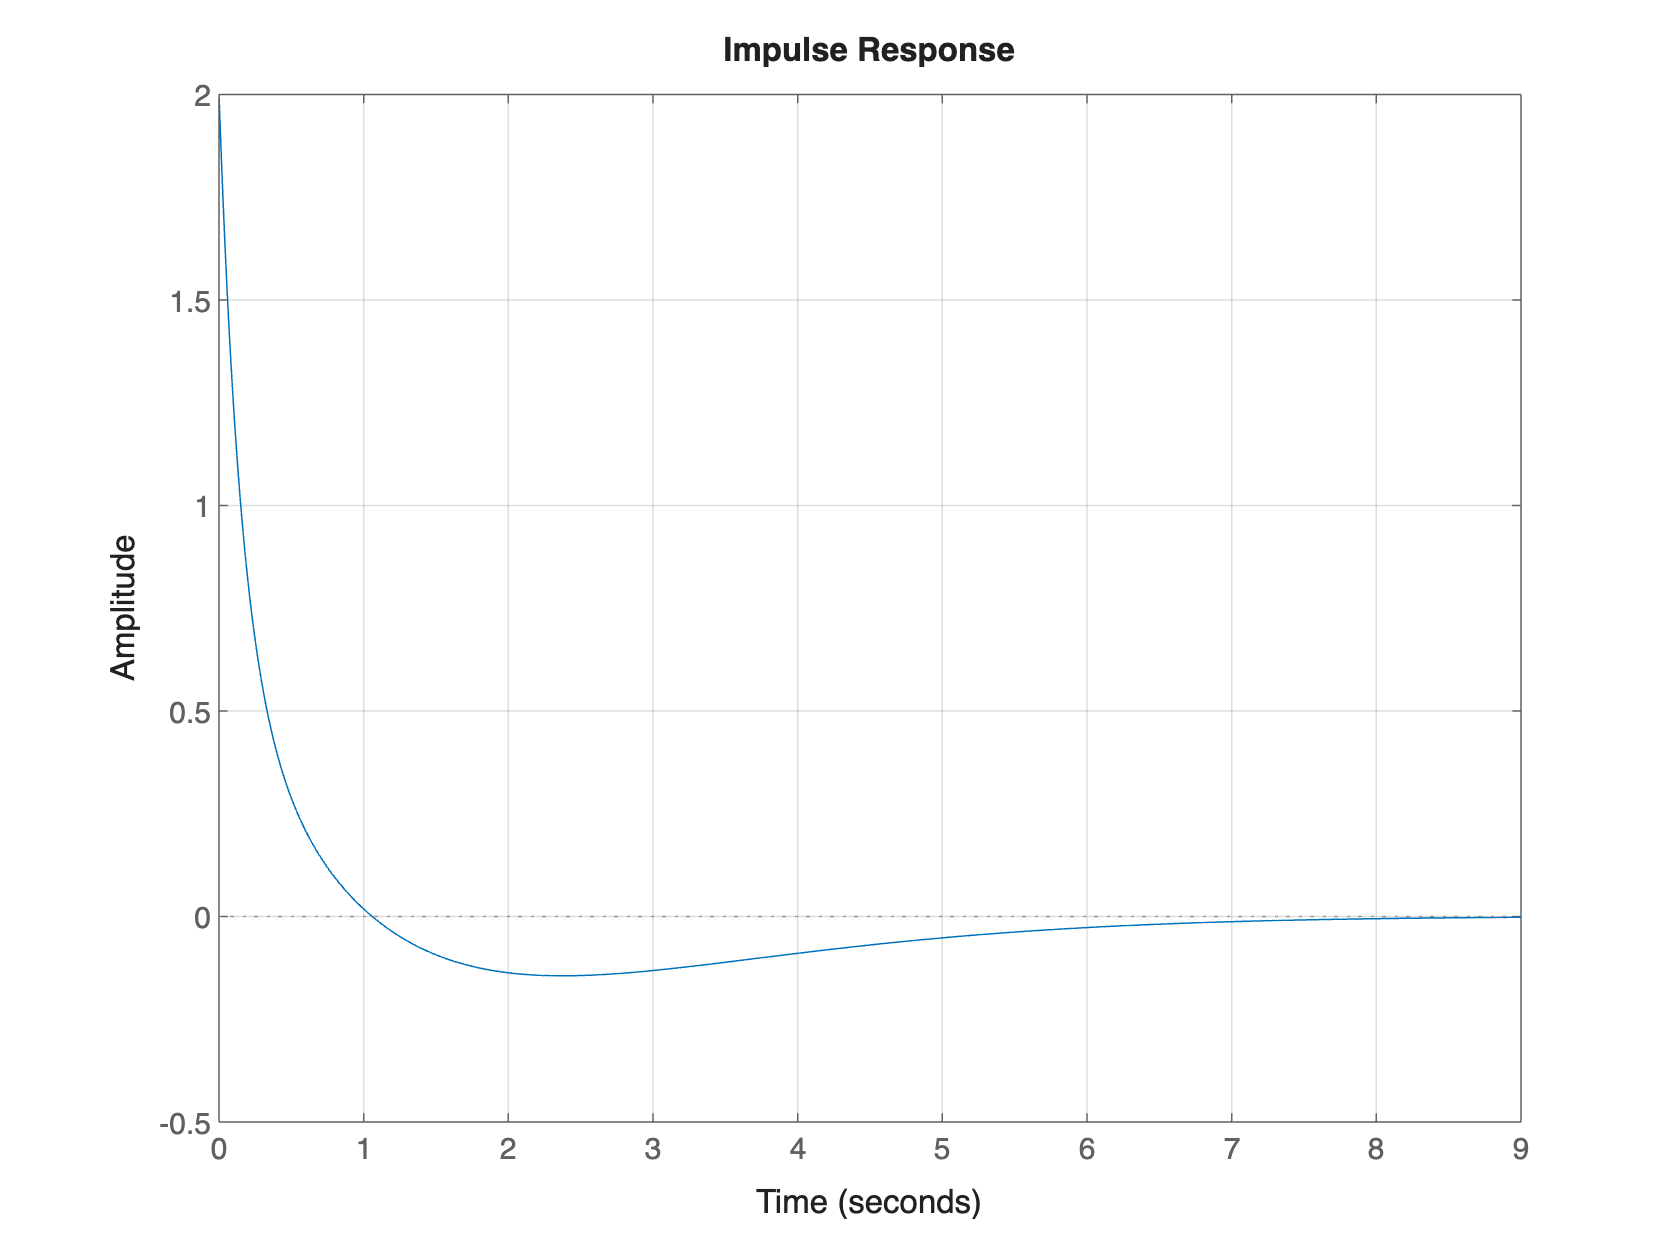

impulse(Vout), grid